clear;
N=10^4;
x=randn(1,N);
threshold=0.3;
M=100;
n=1:M;

Under_treshold=nnz(x(n)<threshold); 
txt_UT="Samples under threshold: " + num2str(Under_treshold);
Over_treshold=nnz(x(n)>threshold); 
txt_OT="Samples over threshold: " + num2str(Over_treshold);

Theoretical_Under_treshold=normcdf(threshold); 
txt_TUT="Expected samples under threshold: " + num2str(Theoretical_Under_treshold*length(x(n)));
Theoretical_Over_treshold=normcdf(threshold,'upper'); 
txt_TOT="Expected samples over threshold: " + num2str(Theoretical_Over_treshold*length(x(n)));

mu=0; sigma=1;
true_pdf=makedist('Normal',mu,sqrt(sigma));
true_pdf_x = linspace(min(x), max(x), N); % Definer x-verdier for den teoretiske pdf-en
true_pdf_y = pdf(true_pdf, true_pdf_x); % Beregn y-verdier for den teoretiske pdf-en

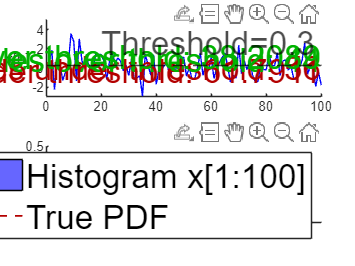

figure;
subplot(2,1,1);
hold on;
plot(n,x(n),'Color', [0 0 1]);
yline(threshold,'--',['Threshold=', num2str(threshold)],'Color', 'k','FontSize',20);
text(M,threshold-0.2,txt_UT,'HorizontalAlignment','right','Color', [0.7 0 0],'FontSize',20);
text(M,threshold+0.6,txt_OT,'HorizontalAlignment','right','Color', [0 0.7 0],'FontSize',20);
text(M,threshold-0.5,txt_TUT,'HorizontalAlignment','right','Color', [0.7 0 0],'FontSize',20);
text(M,threshold+0.9,txt_TOT,'HorizontalAlignment','right','Color', [0 0.7 0],'FontSize',20);
ylabel("x[n]");
xlabel("n");
set(get(gca,'ylabel'),'rotation',0);
subplot(2,1,2);
hold on;
histogram(x,'Normalization','pdf','FaceColor', [0 0 1]);
plot(true_pdf_x, true_pdf_y, '--','Color', [0.7 0 0],'LineWidth',1);
legend("Histogram x[1:"+num2str(M)+"]","True PDF",'FontSize',20);

Oppgave 2

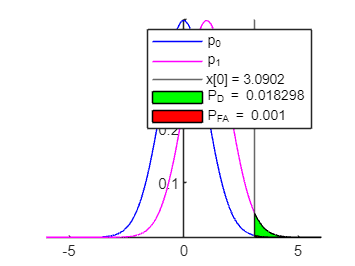

lim=-6:1/400:6;
p0=normpdf(lim, 0, 1); % H0
p1=normpdf(lim, 1, 1); % H1

lambda=exp(qfuncinv(10^-3) - 0.5);
x0=log(lambda) + 0.5; %treshold ~
Pfa=qfunc(x0);
Pd=qfunc(x0 - 1);

figure;
ax = gca;
ax.YAxisLocation = 'origin';
ax.XAxisLocation = 'origin';
hold on;
plot(lim, p0, 'b'); % Plot p1 in blue
plot(lim, p1, 'm'); % Plot p2 in magenta
xline(x0);

% Find indices corresponding to x0
idx_x0 = find(lim >= x0, 1);


% Fill area under p2 (H1) curve with green
fill([lim(idx_x0:end), lim(end), lim(end), lim(idx_x0)], ...
     [p1(idx_x0:end), 0, 0, p1(end)], 'g');

% Fill area under p1 (H0) curve with red
fill([lim(idx_x0:end), lim(end), lim(end), lim(idx_x0)], ...
     [p0(idx_x0:end), 0, 0, p0(end)], 'r');

legend("p_0","p_1","x[0] = "+x0,"P_D = "+Pd,"P_{FA} = "+Pfa)
hold off;

Oppgave 4

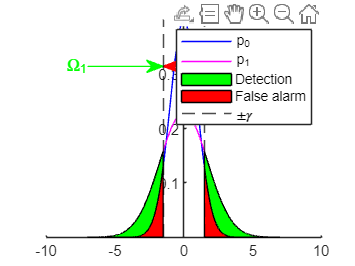

sigma0=1;
sigma1=sqrt(3)*sigma0;
lim=-7:1/400:7;
p0=normpdf(lim,0,sigma0);
p1=normpdf(lim,0,sigma1);

lambda=0.35;
gamma=(2*(sigma0*sigma1)^2)/(sigma1^2-sigma0^2)*log(lambda*sigma1/sigma0);
idx_Ugamma = find(lim >= abs(gamma), 1);
idx_Lgamma = find(lim >= -abs(gamma), 1);

figure;
ax = gca;
ax.YAxisLocation = 'origin';
ax.XAxisLocation = 'origin';
hold on;
plot(lim, p0, 'b');
plot(lim, p1, 'm');
xline([-gamma gamma],'--k');


% Fill area under p1 (H1) curve with green for lim >= gamma
fill([lim(idx_Ugamma:end), lim(end), lim(end), lim(idx_Ugamma)], ...
     [p1(idx_Ugamma:end), 0, 0, p1(end)], 'g');
% Fill area under p1 (H1) curve with green for lim <= -gamma
fill([lim(1:idx_Lgamma), lim(idx_Lgamma)], ...
     [p1(1:idx_Lgamma), 0], 'g');

% Fill area under p0 (H0) curve with red for lim >= gamma
fill([lim(idx_Ugamma:end), lim(end), lim(end), lim(idx_Ugamma)], ...
     [p0(idx_Ugamma:end), 0, 0, p0(end)], 'r');
% Fill area under p0 (H0) curve with red for lim <= -gamma
fill([lim(1:idx_Lgamma), lim(idx_Lgamma)], ...
     [p0(1:idx_Lgamma), 0], 'r');

max_sum = (max(abs(p0)) + max(abs(p1))) / 2;

anArrow = annotation('textarrow');
anArrow.Parent = gca;
anArrow.X = [lim(1),-abs(gamma)]; 
anArrow.Y = [max_sum ,max_sum];
anArrow.String = '\Omega_1';
anArrow.Color = 'green';

anArrow = annotation('textarrow');
anArrow.Parent = gca;
anArrow.X = [lim(end),abs(gamma)]; 
anArrow.Y = [max_sum ,max_sum];
anArrow.String = '\Omega_1';
anArrow.Color = 'green';

anArrow = annotation('doublearrow');
anArrow.Parent = gca;
anArrow.X = [-abs(gamma), abs(gamma)]; % X-coordinates
anArrow.Y = [max_sum, max_sum]; % Y-coordinates
anArrow.Color = 'red'; % Arrow color
text(0.01, max_sum*0.98, '\Omega_0', 'Color', 'r', 'FontSize', 12);

legend("p_0","p_1","\pm\gamma","","Detection","","False alarm");